clear;
close all;
clc;

img = imread("monarch.bmp");
img = img(:,:,1);
%img = imresize(img, 0.5);
%[n,m] = size(img)
%img = img(1:n-mod(n,8),1:m-mod(m,8));

%I = im2double(img);
I = double(img);
T = dctmtx(8);

dct = @(block_struct) T * block_struct.data * T';
B = blockproc(I, [8,8], dct);

mask = [1, 1, 1, 1, 0, 0, 0, 0;
        1, 1, 1, 0, 0, 0, 0, 0;
        1, 1, 0, 0, 0, 0, 0, 0;
        1, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0];

Q = 10;
Q_base = [16 11 10 16 24 40 51 61;
         12 12 14 19 26 58 60 55;
         14 13 16 24 40 57 69 56;
         14 17 22 29 51 87 80 62;
         18 22 37 56 68 109 103 77;
         24 35 55 64 81 104 113 92;
         49 64 78 87 103 121 120 101;
         72 92 95 98 112 100 103 99];

if Q < 50
    S = 5000/Q;
else
    S = 200 - 2*Q;
end

Q_matrix = floor((S*Q_base + 50) / 100);
Q_matrix(Q_matrix == 0) = 1;  % Avoid divide by zero

B2 = blockproc(B,[8 8],@(block_struct) round(block_struct.data ./ Q_matrix));
B2 = int32(B2);

invdct = @(block_struct) T' * block_struct.data * T;
I2 = blockproc(double(B2),[8 8],invdct);
I2 = I2 - min(I2,[],'all')

I2 =     2.1499    2.1499    2.1499    2.1499    2.1499    2.1499    2.1499    2.1499    2.2749    2.2749    2.2749    2.2749    2.2749    2.2749    2.2749    2.2749    2.2165    2.1736    2.1358    2.1676    2.3056    2.5287    2.7615    2.9100    2.6782    2.7310    2.8285    2.9559    3.0939    3.2213    3.3189    3.3717    3.2749    3.2749    3.2749    3.2749    3.2749    3.2749    3.2749    3.2749    3.3999    3.3999    3.3999    3.3999    3.3999    3.3999    3.3999    3.3999    3.2749    3.2749
    2.1499    2.1499    2.1499    2.1499    2.1499    2.1499    2.1499    2.1499    2.2749    2.2749    2.2749    2.2749    2.2749    2.2749    2.2749    2.2749    2.2165    2.1736    2.1358    2.1676    2.3056    2.5287    2.7615    2.9100    2.6782    2.7310    2.8285    2.9559    3.0939    3.2213    3.3189    3.3717    3.2749    3.2749    3.2749    3.2749    3.2749    3.2749    3.2749    3.2749    3.3999    3.3999    3.3999    3.3999    3.3999    3.3999    3.3999    3.3999    3.2749    

I2 = uint8(I2/max(I2, [], "all")*255);

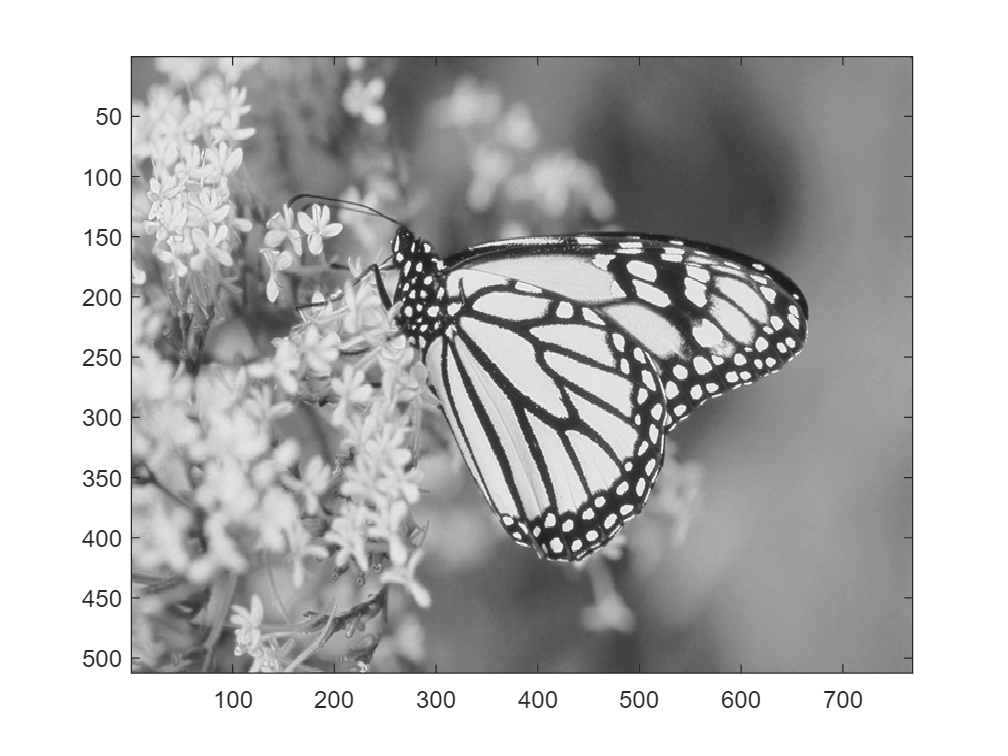

imagesc(I)
colormap("gray")
clim([0,255])

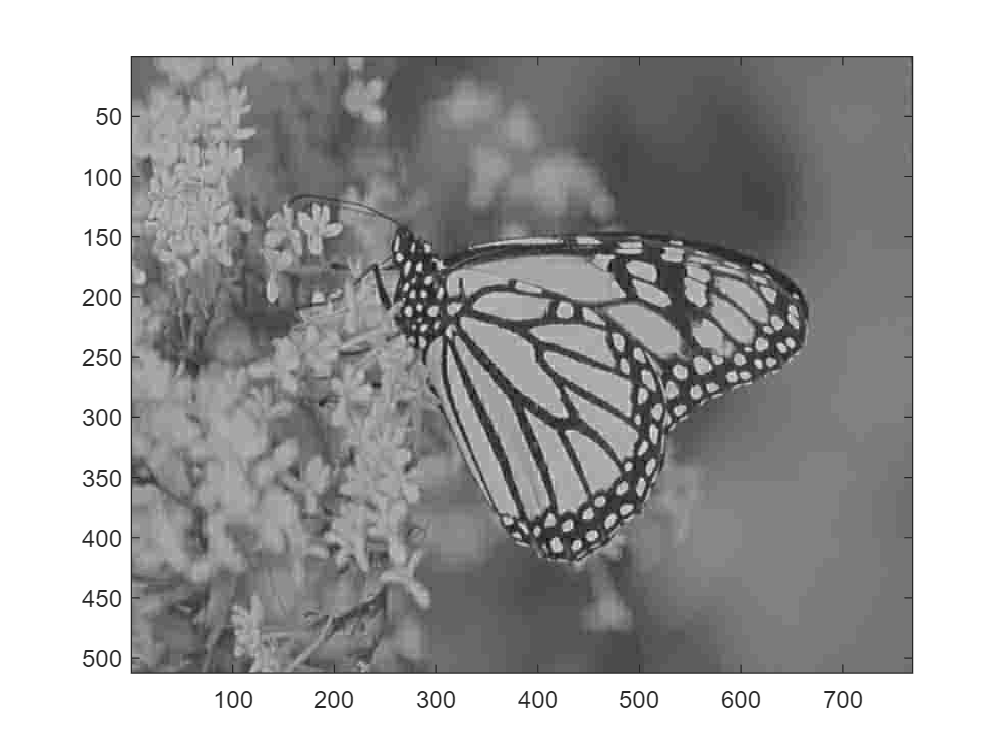

imagesc(I2)
colormap("gray")
clim([0,255])

nz = nnz(B2)

nz = 14017

total = numel(B2)

total = 494400

comp_rat = total/nz

comp_rat = 35.2715